## Group assignment 12 - Charging condensator

I et elektrisk kredsløb måles opladningen af en kondensator gennem en modstand.

Opladningsforløbet forventes at følge formlen:


$$X_1 \left(t\right)=A*\left(1-e^{-k*t} \right)$$


hvor A er en konstant(indsgangsspændingen), og $k=\frac{1}{\textrm{RC}}$ er en konstant bestemt af kredsløbs-komposanterne. I den udførte måling er A=5 , mens k pga. usikkerheden i komponentværdierne er normalfordelt k ~ N(1000, 160000).

1) Lav en stokastisk model af opladningen af kondensatoren.

A = 5;

kmean = 1000;
kdiv = sqrt(160000);

t1 = 0:0.1:10;
k = @()randn()*kdiv+kmean;
x1t = @(t)A*(1-exp(-k()*t*10^-3));

2) Skitser i Matlab fem realisationer af den stokastiske model $X_1 \left(t\right)$ for 0<=t<=10.

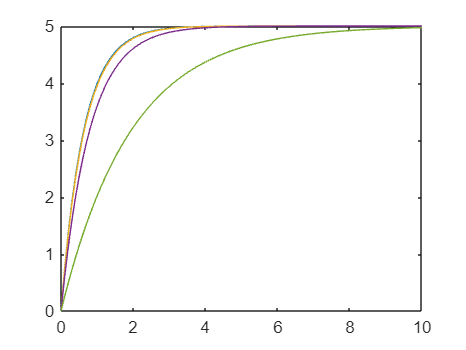

reals = zeros(5,length(t1));
for i=1:5
    reals(i,:) = x1t(t1);
end

figure;
for i=1:5
    plot(t1, reals(i,:));
    hold on;
end
hold off;

3) Er processen X1(t) WSS (Wide sense stationary) og ergodisk?

Da processen er afhængig af tiden betyder det at processen ikke er WSS og da den ikke er WSS er den derfor heller ikke ergodisk.

Ud over det forventede opladningsforløb måles der også noget støj $W\left(t\right)~U\left(-0\ldotp 1,0\ldotp 1\right)$.

4) Lav en stokastisk model X2(t) der inkluderer støjen.

wt = @()((rand(1, length(t1))*2-1)*0.1);
x2t = @(t)x1t(t)+wt();


5) Skitser i Matlab tre realisationer af den stokastiske model X2(t) for 0<=t <= 10.

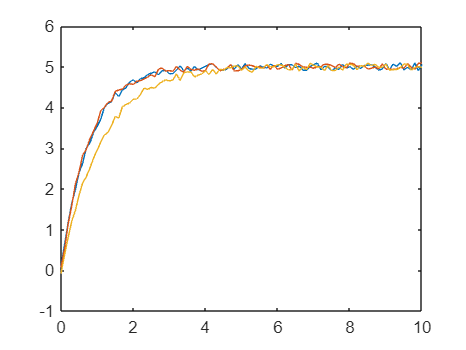

amount = 3;
reals2 = zeros(amount, length(t1));
for i = 1:amount
    reals2(i,:) = x2t(t1);
end
figure;
plot(t1, reals2);

6) Er processen X2(t) WSS (Wide Sense Stationary) og ergodisk?

Fordi processen stadig er afhængig af tid er både ensemble middelværdi og ensemble variansen også afhængig af tid og dermed ikke WSS og fordi den ikke er WSS er den derfor heller ikke ergodisk.

Signalet samples digitalt med en sample-rate på 10 samples pr. tidsenhed [ms].

7) Lav en stokastisk model X3(n) for det samplede signal.

8) Skitser i Matlab tre realisationer af den stokastiske model X3(n) for 0<=t <= 10.

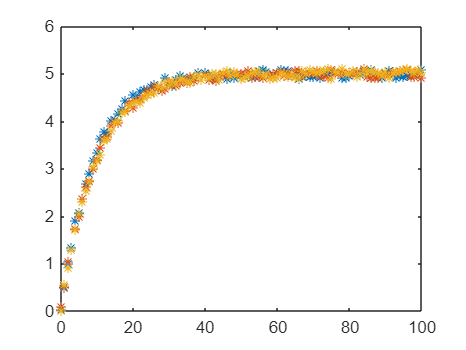

amount = 3;
reals3 = zeros(amount, length(t1));
for i = 1:amount
    reals3(i,:) = x2t(t1);
end
figure;
plot(t1*10, reals3, '*');

9) Er processen Xn(n) WSS (Wide Sense Stationary) og ergodisk?

Nej, den er stadig hverken WSS eller ergodisk.